# Colour Transfer

Loading files into current working space

% Repository
rep = './Pictures/';                        % Image location

% File names
source = 'meal.jpg';                       % Source file-name
target = 'Com.png';                       % Target file-name

% Load images
[x_,x_map] = imread([rep, source]);         % Load source
[y_,y_map] = imread([rep, target]);         % Load target

Parameter calibration

k = 200;                                    % Number of clusters
algorithm = 'PD'                            % Primal-Dual or Entropic

algorithm = 'PD'

Image pre-processing

% Sub-sampling
x0 = x_;                                    % Copy base source
y0 = y_;                                    % Copy base target

[Nx_X, Ny_X] = size(x_, [1,2]);             % Dimensions of source
[Nx_Y, Ny_Y] = size(y_, [1,2]);             % Dimensions of target

% Coordinated grid
% Spatial coordonates are considered as colors in [0;255]
[YY_X,XX_X] = meshgrid(linspace(0,255,Ny_X), linspace(0,255,Nx_X));
XX_X = reshape(XX_X, [1 Nx_X * Ny_X]);
YY_X = reshape(YY_X, [1 Nx_X * Ny_X]);

[YY_Y,XX_Y] = meshgrid(linspace(0,255,Ny_Y), linspace(0,255,Nx_Y));
XX_Y = reshape(XX_Y, [1 Nx_Y * Ny_Y]);
YY_Y = reshape(YY_Y, [1 Nx_Y * Ny_Y]);

% Reshape original pictures and represent them as coordinated objects
X_ = double( reshape(x_,[],3)' );           % Reshape source by channel
Y_ = double( reshape(y_,[],3)' );           % Reshape target by channel

X_ = [X_; XX_X; YY_X];                      % Add coordinates to source
Y_ = [Y_; XX_Y; YY_Y];                      % Add coordinates to target

Perform super-pixel clustering

N_x = Nx_X * Ny_X;                          % Flattened dimension of source
N_y = Nx_Y * Ny_Y;                          % Flattened dimension of target

addpath('./toolbox/')                       % Path to toolbox
% Run SCALP Algorithm 
Timing = tic;
[K_x,Mu_x] = SCALP_segmentation(single(x_), k);

SCALP Super-pixel segmentation


Timing = toc(Timing);
disp('First took ' + string(Timing) + 's')

First took 41.1543s


Timing = tic;
[K_y,Mu_y] = SCALP_segmentation(single(y_), k);

SCALP Super-pixel segmentation


Timing = toc(Timing);
disp('First took ' + string(Timing) + 's')

First took 88.4814s


% Get biggest value of segmentation
KK_x = max(K_x(:));
KK_y = max(K_y(:));

% 5 x k  matrix with k clusters
Mu_x = Mu_x'; Mu_y = Mu_y';
% 1 x N matrix of assignation of k clusters 'C'
K_x  = K_x'; K_y = K_y';


% Extract cluster information
% Compute measure
P_x = sum( (ones(1,KK_x)' * K_x) == (1:1:KK_x)' * ones(1,N_x) , 2)/N_x;
P_y = sum( (ones(1,KK_y)' * K_y) == (1:1:KK_y)' * ones(1,N_y) , 2)/N_y;


% Image representation for final synthesis
Pixel_List_X = create_list(x_, Nx_X, Ny_X);
Pixel_List_Y = create_list(y_, Nx_Y, Ny_Y);

% Mean and Variance for each cluster
[Mean_CX Var_CX] = compute_stat_clusters(Pixel_List_X, reshape(K_x,Nx_X,Ny_X,1), ...
                                         KK_x, Nx_X, Ny_X, 1e-1, 1e1);
[Mean_CY Var_CY] = compute_stat_clusters(Pixel_List_Y, reshape(K_y,Nx_Y,Ny_Y,1), ...
                                         KK_y, Nx_Y, Ny_Y, 1e-1, 1e1);

Var_X = Var_CX{1};
for k=2:KK_x
    Var_X = blkdiag(Var_X, Var_CX{k});
end
Var_X = sparse(Var_X);

Var_Y = Var_CY{1};
for k=2:KK_y
    Var_Y = blkdiag(Var_Y, Var_CY{k});
end
Var_Y = sparse(Var_Y);

Distance matrix

% Remove spatial coordonates for the clustering used in Optimal Transport
Mu_x = Mu_x(1:3,:);
Mu_y = Mu_y(1:3,:);

C_X = sum(Mu_x.^2,1)' * ones(1, KK_y);
C_Y = ones(KK_x, 1) * sum(Mu_y.^2,1);

dc_xy = C_X + C_Y - 2 * (Mu_x' * Mu_y);

Run algorithm

if algorithm == 'PD'
    [Flow, obj, y_1, y_2, temp] = Primal_Dual(dc_xy, P_x, P_y, false);
end

ans = 1×2 int16 row vector
      -4    1000


if algorithm == 'ER'
    [Flow, obj] = Entropy_Regularisation(dc_xy, P_x, P_y, 0.1, false);
end
%plotGamma(Mu_x, Mu_y, gam, KK_x, KK_y)

Color Transfer and Image synthesis

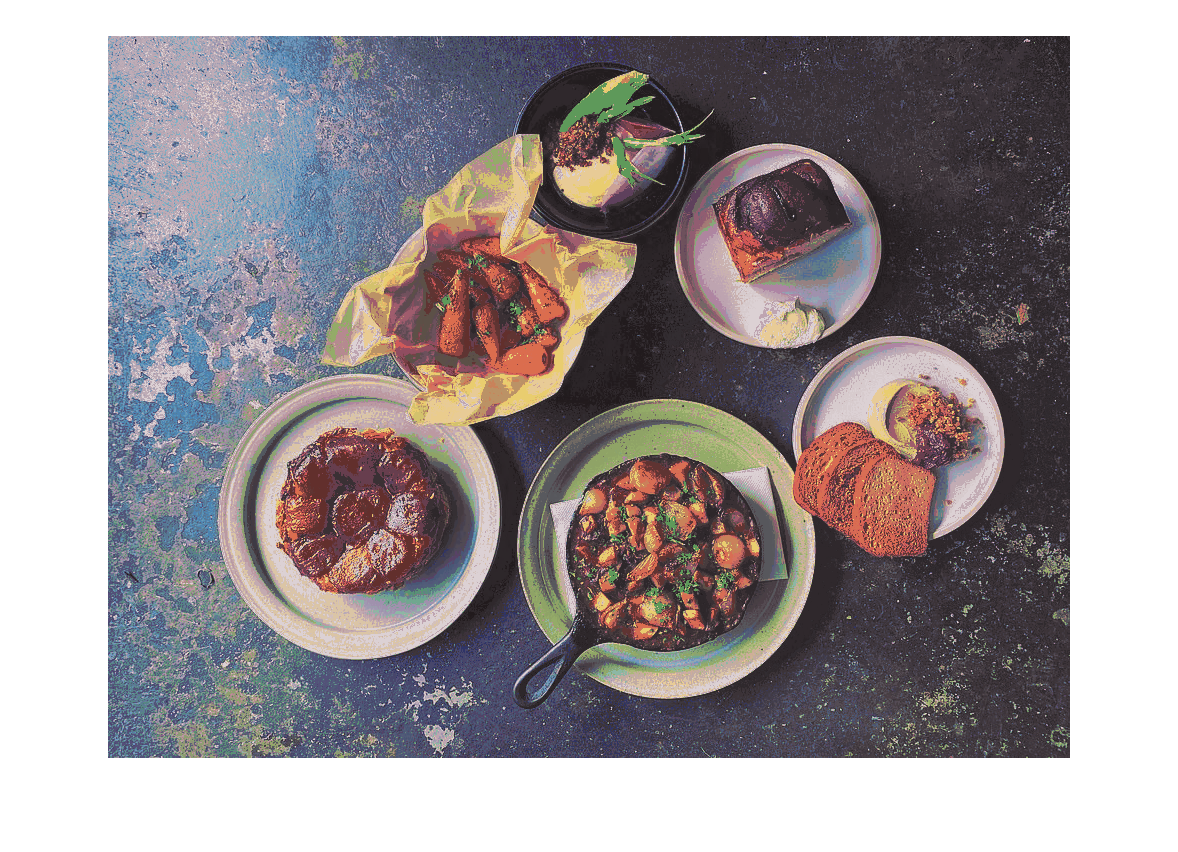

Pixel_List_X = create_list(x_, Nx_X, Ny_X);
XY_ = synthesis_fast(Pixel_List_X, Mean_CX, Var_X, Mean_CY, Flow, Nx_X, Ny_X, KK_x);
%XY_ = synthesis(Pixel_List_X, Mean_CX,  Var_CX, Mean_CY, Flow, Nx_X, Ny_X, KK_x);

xy_ = reshape(XY_', Nx_X, Ny_X, 3);

imshow(uint8(xy_))

imwrite(uint8(xy_), strcat('Solutions/', source(1:end-4),'-',target(1:end-4),'-',algorithm, '.png') )